# Materials classification - A1

clc; clear all; close all;

## Import dataset

image_data_folder = "Data\Train\image\";
mask_data_folder = "Data\Train\mask\";
image = Images_import(image_data_folder);
mask = Images_import(mask_data_folder);

% Each row of each matrix contains the paths of the images of an specific material, being
% the order of the rows: fabric, foliage, glass, leather, metal, paper,
% plastic, tone, water and wood
% Now, to have acces to an image we only have to do:
% imread(image(i,j)) or imread(mask(i,j))

## Create targets

for idx = 1:length(image)
    if contains(image(idx).path, "fabric")
        image(idx).target = "fabric";
        mask(idx).target = "fabric";
    elseif contains(image(idx).path, "foliage")
        image(idx).target = "foliage";
        mask(idx).target = "foliage";
    elseif contains(image(idx).path, "glass")
        image(idx).target = "glass";
        mask(idx).target = "glass";
    elseif contains(image(idx).path, "leather")
        image(idx).target = "leather";
        mask(idx).target = "leather";
    elseif contains(image(idx).path, "metal")
        image(idx).target = "metal";
        mask(idx).target = "metal";
    elseif contains(image(idx).path, "paper")
        image(idx).target = "paper";
        mask(idx).target = "paper";
    elseif contains(image(idx).path, "plastic")
        image(idx).target = "plastic";
        mask(idx).target = "plastic";
    elseif contains(image(idx).path, "stone")
        image(idx).target = "stone";
        mask(idx).target = "stone";
    elseif contains(image(idx).path, "water")
        image(idx).target = "water";
        mask(idx).target = "water";
    elseif contains(image(idx).path, "wood")
        image(idx).target = "wood";
        mask(idx).target = "wood";
    end
end

### Create image set

% Apply the mask and save only the foreground object
reqSize = 30;   % Size of the image patch for subsequent analysis and model training
imgData = [];
croppedTempImg = zeros(reqSize, reqSize, 3);
for idx = 1:length(image)
    tempImg = imread(image(idx).path);
    tempMask = imread(mask(idx).path);
    [rowIdx, colIdx] = autoROI(tempMask, reqSize);
    if rowIdx == size(tempMask, 1) && colIdx == size(tempMask, 2)
        disp("Desired ROI not found!\n");
    else
        % If original image is grayscale, convert to RGB
        if size(tempImg,3) == 1
            tempImg = cat(3, tempImg, tempImg, tempImg);
        end
            croppedTempImg(:,:,1) = tempImg(rowIdx:rowIdx+reqSize-1, colIdx:colIdx+reqSize-1, 1);
            croppedTempImg(:,:,2) = tempImg(rowIdx:rowIdx+reqSize-1, colIdx:colIdx+reqSize-1, 2);
            croppedTempImg(:,:,3) = tempImg(rowIdx:rowIdx+reqSize-1, colIdx:colIdx+reqSize-1, 3);
    end
    imgData{idx} = croppedTempImg;
end

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];

## Feature Extraction

### Feature 1: Entropy measure

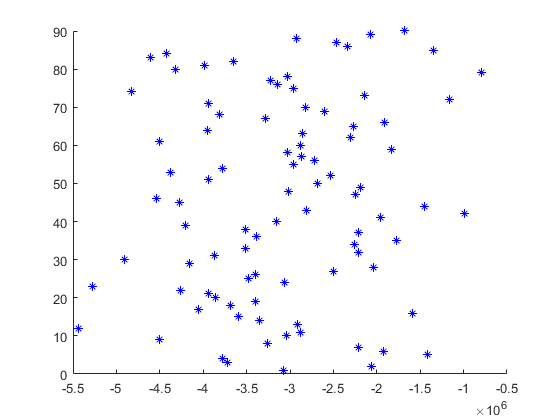

entropyVals = [];
for idx = 1:length(imgData)
    entropyVals(idx) = entropy(im2gray(imgData{idx}(:)));
end
figure; hold on;
for idx = 91:91+length(imgData(:,1:90))
    plot(entropyVals(idx), idx, 'b*');
end
hold off;

% legend(inputs);

### Feature 2: Number of edges

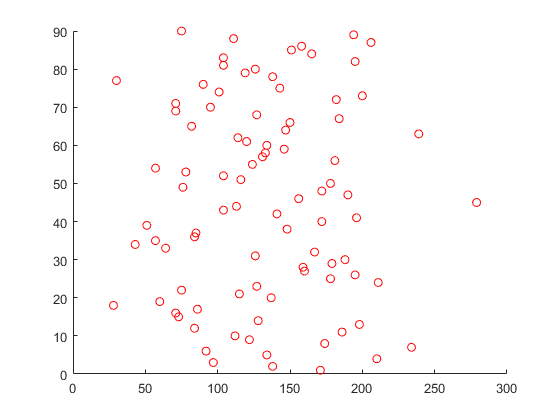

edgeCount = [];
for idx = 1:length(imgData)
    bw = edge(imgData{idx},'canny');
    edgeCount(idx) = nnz(bw);
end

figure; hold on;
for idx = 1:length(imgData(:,1:90))
    plot(edgeCount(idx), idx, 'ro');
end
hold off;

% legend(inputs);

### Feature 3: Std. deviation of image

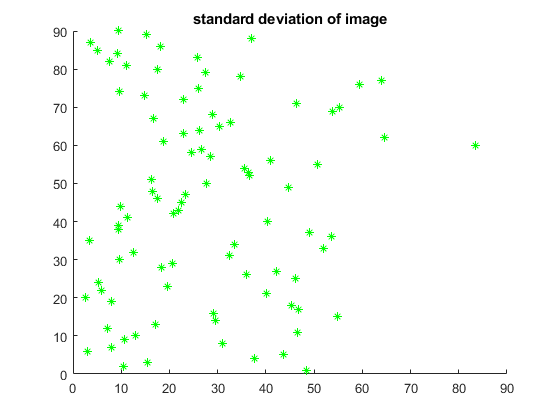

figure; hold on;
for idx = 1:length(imgData(:,1:90))
    imgDev = std(double(imgData{idx}(:)));
    plot(imgDev, idx, 'g*');
end
title("standard deviation of image")
hold off;

% legend(inputs);

## Dividing the variables that need discretization

rng('default')

load edgeCount.mat;
load entropyVals.mat;
load imgDev.mat;
inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];
features = [edgeCount; entropyVals; imgDev]';

nseg = 5;
data = features;
% append new column class, represented for every 100 sequential obs
classCount = 1;
for idx = 1:length(data)
    data(idx,size(features,2) + 1) = classCount;
    if mod(idx,100) == 0
        classCount = classCount + 1;
    end
end

for i = 1:length(data(1,1:end-1))

    var     = data(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end

    for ii = 1:nseg-1
        idxCurrent = intersect(find(data(:,i)>=seg(ii).LB), find(data(:,i)<seg(ii+1).LB));
        data2(idxCurrent,i) = ii;
    end

    idxCurrent = find(data(:,i)>seg(ii+1).LB);
    data2(idxCurrent,i) = ii+1;

end

data2(:,end+1) = data(:,end);


## Data Division

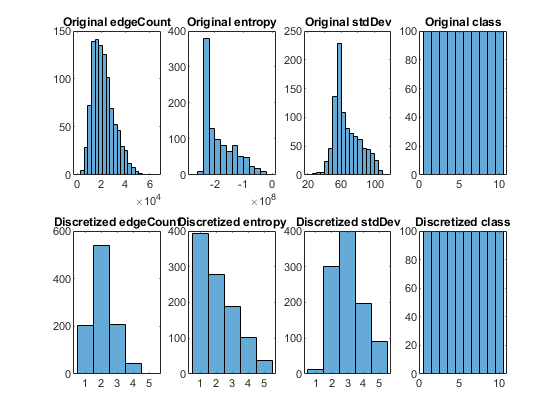

[row, col]      = size(data2);
varLabels = ["edgeCount", "entropy", "stdDev", "class"];

ii = 1;
for i = 1:col
    subplot(2, col, i);
    histogram(data(:,i)); title("Original " + varLabels(i));

    subplot(2, col, i+col);
    histogram(data2(:,i)); title("Discretized " + varLabels(i));
end

% Test and calibration in the partition below.
partitionRatio = 0.1;
c       = cvpartition(data(:,end), 'Holdout', partitionRatio);
idxCal = test(c);
idxTrain  = training(c);

dataAll  = data2;
dataTrain    = dataAll(idxTrain,  :);
dataCal = dataAll(idxCal, :);


## Learn the structure of a BN

[row, col]      = size(dataTrain);

ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(dataTrain');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(dataTrain(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 2, 'verbose', 'yes');


node 1, empty score -1035.3607

node 2, empty score -1280.2613
considering adding 1 to 2, score -1200.3484
* adding 1 to 2, score -1200.3484

node 3, empty score -1210.9280
considering adding 1 to 3, score -1173.6247
considering adding 2 to 3, score -1003.8671
* adding 2 to 3, score -1003.8671
considering adding 1 to 3, score -1085.3069

node 4, empty score -2107.9795
considering adding 1 to 4, score -2057.9691
considering adding 2 to 4, score -2168.7017
considering adding 3 to 4, score -2175.2366
* adding 1 to 4, score -2057.9691
considering adding 2 to 4, score -2393.5854
considering adding 3 to 4, score -2368.3740


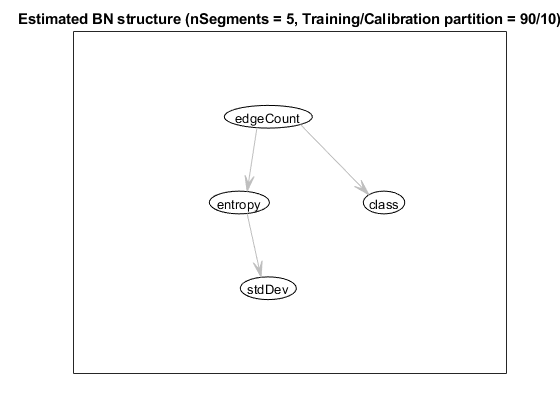

BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end

figure;
draw_graph(BNhat.dag, varLabels);
title(sprintf("Estimated BN structure (nSegments = %d, Training/Calibration partition = %d/%d)", nseg, 100-partitionRatio*100, partitionRatio*100));

## Training

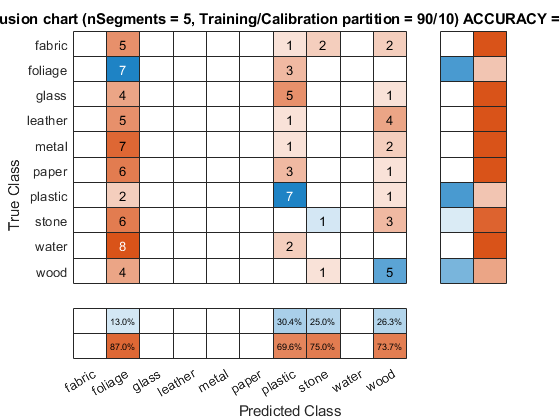

engine       = global_joint_inf_engine(BNhat);
[rowT, colT] = size(dataCal);

for j = 1:rowT
    evidence     = [];
    evidence     = cell(1,colT);
    for i = 1:col-1
        evidence{variable(i).node} = dataCal(j,i);
    end
    [engine, logLikelihood] = enter_evidence(engine, evidence);
    marginal       = marginal_nodes(engine, variable(end).node);
    totProb        = sum(marginal.T(:));
    dataPoint(j).M = marginal.T ./ totProb;
    [~, dataPoint(j).yhat] = max(dataPoint(j).M);
end

Ypred = categorical([dataPoint.yhat]');
Ytrue = categorical(dataCal(:,end));

accuracy = sum(Ypred==Ytrue)/length(Ytrue);
ACCURACY_CAL(nseg,nseg) = accuracy;
figure;
cm = confusionmat(Ytrue, Ypred);
results = confusionchart(cm, inputs, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
results.title(sprintf("Confusion chart (nSegments = %d, Training/Calibration partition = %d/%d) ACCURACY = %0.2f%%", nseg, 100-partitionRatio*100, partitionRatio*100, accuracy*100));

## Testing